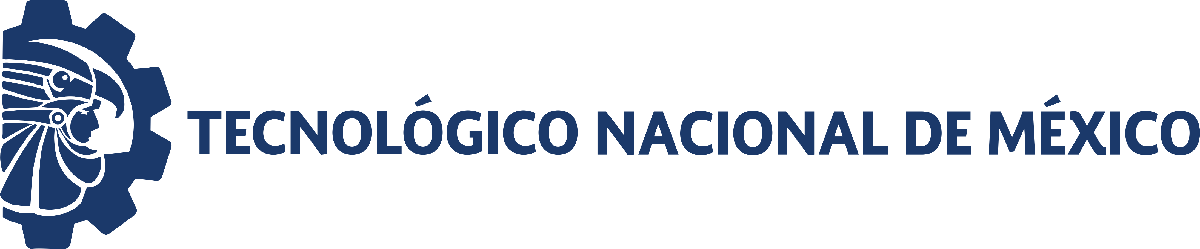                                 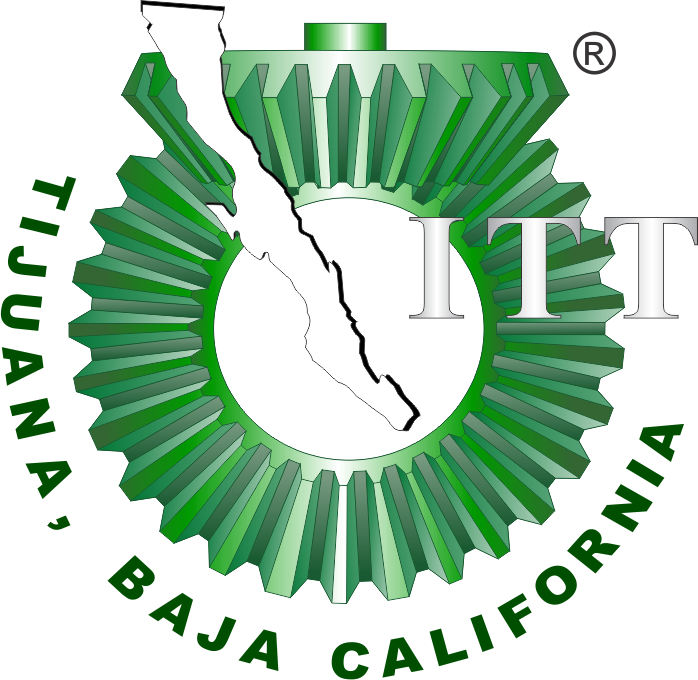

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 3: Algoritmos de regresión no lineal

## Información general

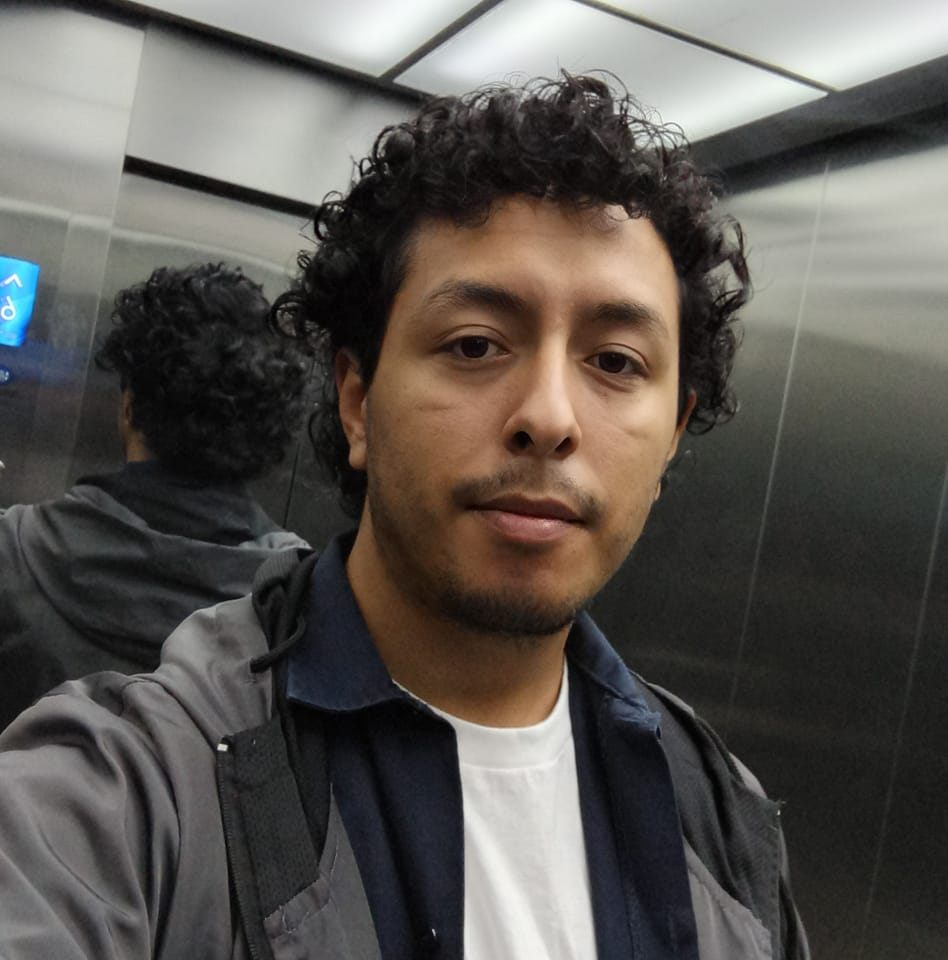

Nombre del alumno: **Cipriano Camacho Mario Tolentino**

Número de control: **20211961**

Correo institucional: **l20211961@tectijuana.edu.mx**

Carrera: **Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetivo:** aaa

## Simulation data

%Datos de la simulación
clc; clear; close all; warning('off','all')

## aaa

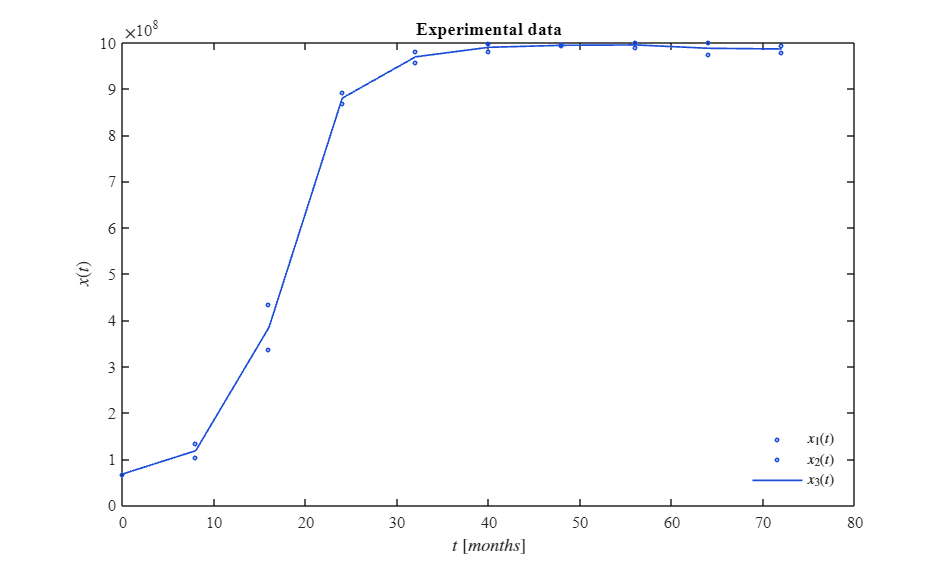

sys = readmatrix('data.csv');
to = sys(:,1); x1o = sys(:,2); x2o = sys(:,3);
xo = mean([x1o, x2o], 2);
plotData(to,x1o,x2o,xo); ttl = ''; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'data.pdf','ContentType','vector')

xmax = max(xo);

## Nonlinear regression: Logistic growth law

b = 1/xmax;
k0 = 1E-3;
mdl_logistic = logistic(to,xo,k0,b); x1a = mdl_logistic.Fitted; 


Parameter b: 1.0052e-09
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student values: 2.2622
R-squared: 0.9757
Corrected AIC (n/pars < 40): 388.1464

    Parameters    Estimate       SE          MoE             CI95             Pvalue  
    __________    ________    _________    ________    _________________    __________

       "k"        0.16158     0.0095842    0.021681    0.1399    0.18327    4.0727e-08



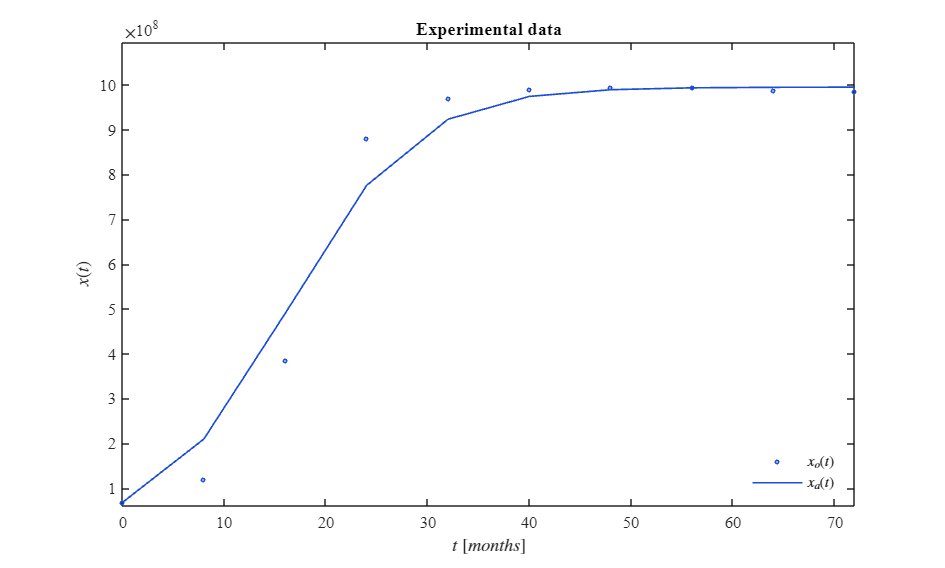

plotFit(to,xo,x1a)
exportgraphics(gcf, 'Logistic growth law.pdf','ContentType','vector')

## Nonnear regression: Allometric  spheare growth law

b = 1/xmax;
k0 = 1E-3;
mdl_logistic = logistic(to,xo,k0,b); x2a = mdl_logistic.Fitted; 


Parameter b: 1.0052e-09
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student values: 2.2622
R-squared: 0.91801
Corrected AIC (n/pars < 40): 400.3094

    Parameters    Estimate      SE       MoE            CI95            Pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         228.81     31.385    70.999    157.82    299.81    4.6116e-05



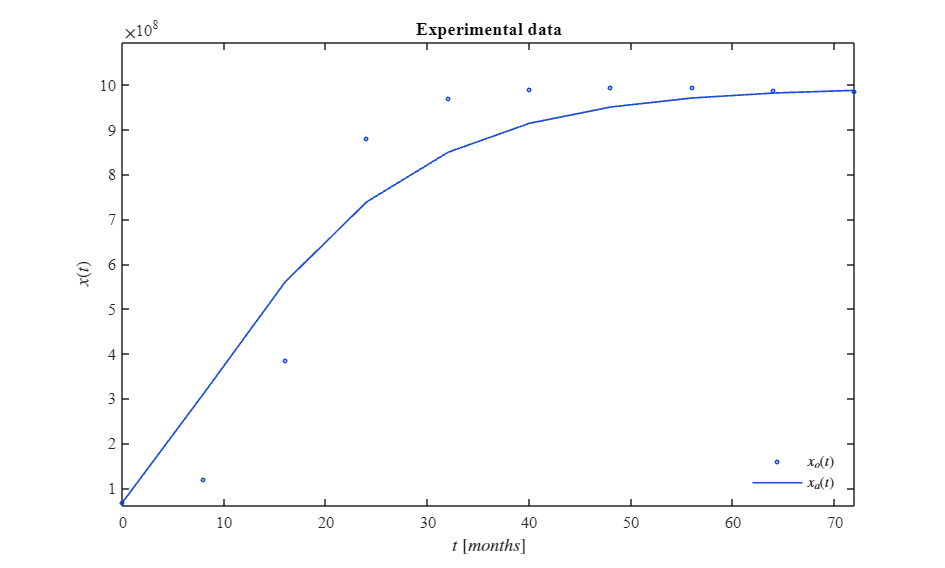

plotFit(to,xo,x2a) 
exportgraphics(gcf, 'Allometric  spheare growth law.pdf','ContentType','vector')

## Nonnear regression: Allometric  fractal growth law

b = 1/xmax;
k0 = 1E-3;
mdl_logistic = logistic(to,xo,k0,b); x3a = mdl_logistic.Fitted; 


Parameter b: 1.0052e-09
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student values: 2.2622
R-squared: 0.92352
Corrected AIC (n/pars < 40): 399.6135

    Parameters    Estimate      SE       MoE            CI95            Pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         56.982     7.4297    16.807    40.175    73.789    3.0955e-05



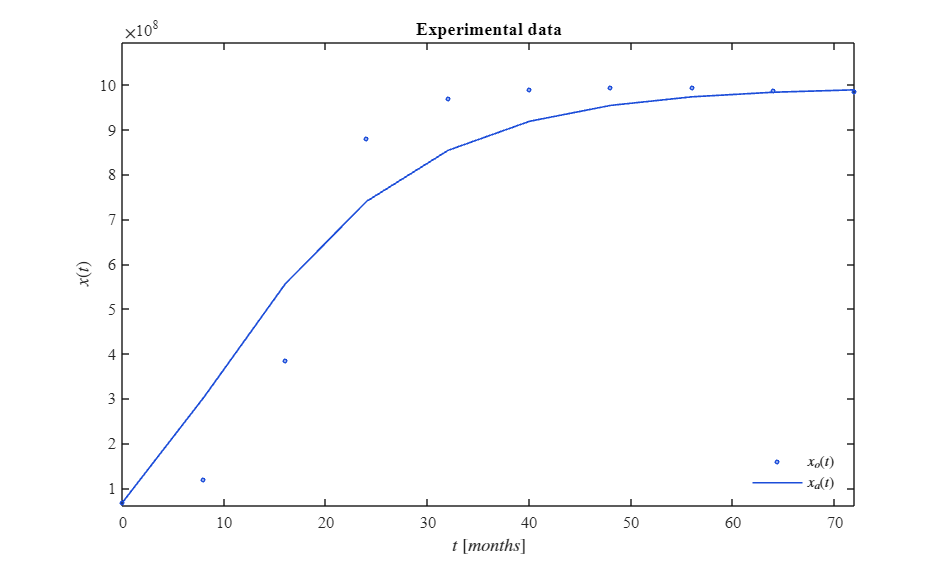

plotFit(to,xo,x3a)
exportgraphics(gcf, 'Allometric  fractal growth law.pdf','ContentType','vector')

## Nonnear regression: Gompertz  Normal growth law

b = 1/log(xmax);
k0 = 1E-3;
mdl_logistic = logistic(to,xo,k0,b); x4a = mdl_logistic.Fitted; 


Parameter b: 0.048267
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student values: 2.2622
R-squared: 0.9385
Corrected AIC (n/pars < 40): 397.4343

    Parameters    Estimate      SE         MoE            CI95            Pvalue  
    __________    ________    _______    _______    ________________    __________

       "k"         1.9245     0.21469    0.48566    1.4389    2.4102    8.8198e-06



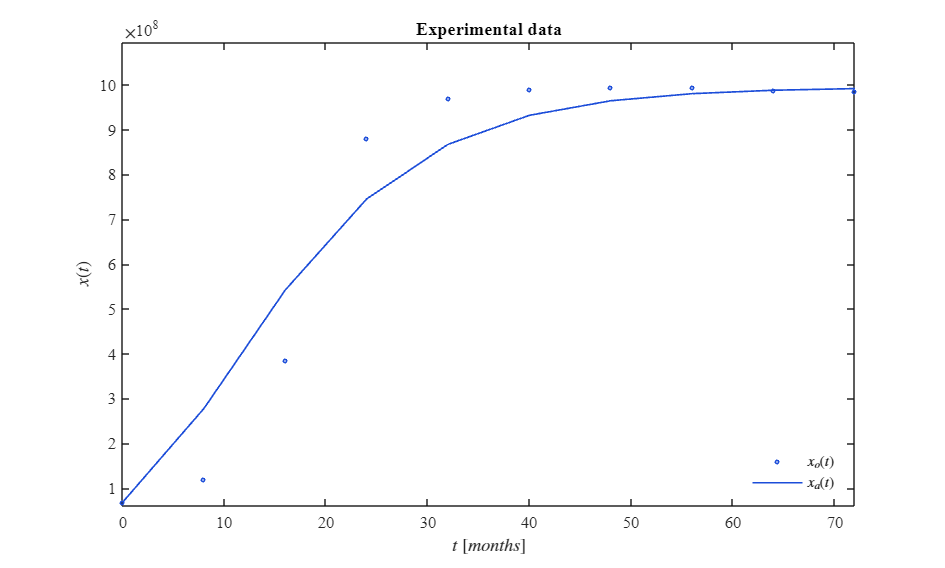

plotFit(to,xo,x4a)
exportgraphics(gcf, 'Gompertz  Normal growth law.pdf','ContentType','vector')

## Nonnear regression: Gompertz  simplified growth law

b = xmax;
k0 = 1E-3;
mdl_logistic = logistic(to,xo,k0,b); x5a = mdl_logistic.Fitted; 


Parameter b: 994854338
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student values: 2.2622
R-squared: 0.9385
Corrected AIC (n/pars < 40): 397.4343

    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

       "k"        0.092892    0.010362    0.023441    0.06945    0.11633    8.8203e-06



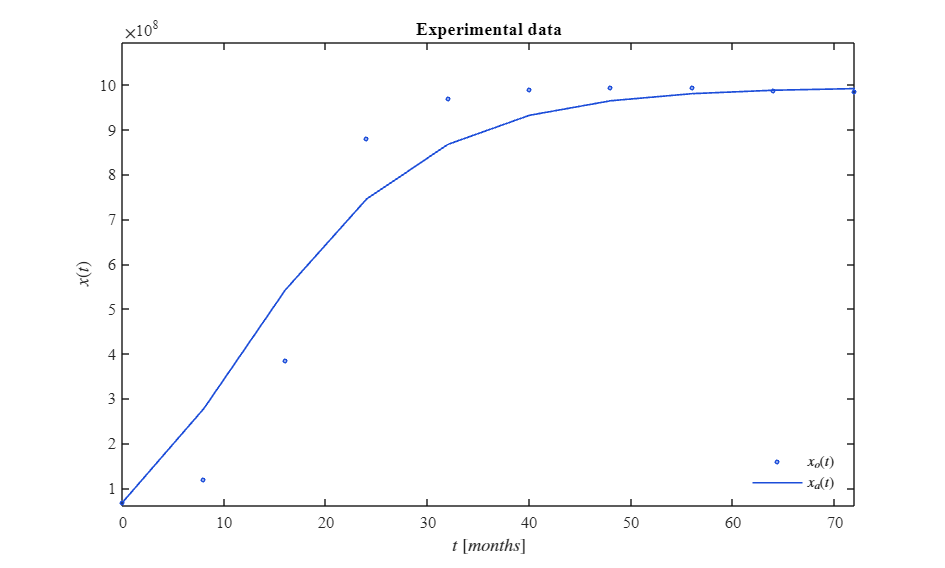

plotFit(to,xo,x5a)
exportgraphics(gcf, 'Gompertz  simplified growth law.pdf','ContentType','vector')

## Functions

function plotData(t,x,y,xm)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])

    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'o','MarkerSize',2,'LineWidth',1,'Color',c1)
    plot(t,y,'o','MarkerSize',2,'LineWidth',1,'Color',c1)
    plot(t,xm,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    % xlim([0, 72]); xticks(0:8:72);
    % ylim([0, 11E8]); yticks(0:1E8:11E8);
    L = legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$');
    title('Experimental data')
    set(L,'Interpreter','latex','Location','Best','Box','off')
end

### Nonlinear regression algorithm: Logistic growth law

function mdl = logistic(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end

        function dx = f(x)
            % dx = k*x*(1 - b*x); 
            % dx = (k*x^(2/3))*(1 - (b*x)^(1/3));
            % dx = (k*x^(3/4))*(1 - (b*x)^(1/4));
            % dx = k*x*(1 - b*log(x));
            dx = k*x*log(b/x);
        end
        
        xi = zeros(length(t),1);
        for j = 1:length(t)
            l = abs(time - t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end
    
    mdl = fitnlm(to,xo,@model,k0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    
    fprintf(['\nParameter b: ', num2str(b)])
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student values: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])

    disp(Results)
end


### Plot fitted and observed data

function plotFit(to,xo,x1a)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])

    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(to,xo,'o','MarkerSize',2,'LineWidth',1,'Color',c1)
    plot(to,x1a,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([min(to), max(to)]);
    ylim([min(xo)*0.9, max(xo)*1.1]);
    L = legend('$x_o(t)$', '$x_a(t)$');
    title('Experimental data')
    set(L,'Interpreter','latex','Location','Best','Box','off')
end